# ECE 580 HW3

Yen-Chun Chen

934559635

### 1. Find the expressions in terms of the element values for the dc gain, the pole frequency (ωo) and the pole  Q (Qp), for the Delyiannis and Rauch filters.

**Delyiannis-Friend Filter:**

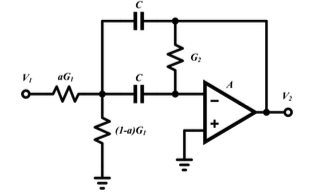

Transfer Function with an ideal op-amp:


$$H\left(s\right)\;=\;-\frac{{\textrm{saCG}}_1 }{s^2 C^2 +2{\textrm{sCG}}_2 +G_1 G_2 }\;=\;-\frac{\frac{{\textrm{saG}}_1 }{C}}{s^2 +s\frac{2G_2 }{C}+\frac{G_1 G_2 }{C^2 }}$$


The DC Gain: $\lim_{s\to 0} H\left(s\right)=\;H\left(0\right)\;=0$

The transfer function for a general second order low-pass filter is given

$H\left(s\right)=\frac{A_v \;{\omega_0 }^2 }{s^2 +\frac{\omega_0 }{Q}s+{\omega_0 }^2 }$ ,  we got that $\omega_0^2 \;=\;\frac{G_1 G_2 }{C^2 }$   Thus, the pole frequency $\omega_0 \;=\;\frac{\sqrt{G_1 G_2 }}{C}$

Pole Q is determined by the coefficient of *s* in the denominator

So we got  $\frac{\omega_0 }{Q_p }\;=\;\frac{2G_2 }{C }\;\to Q_p \;=\;\frac{\sqrt{G_1 G_2 }}{C}\;\frac{C}{2G_2 }\;=\;\frac{1}{2}\sqrt{\frac{G_1 }{G_2 }}\;$

**Rauch Filter:**

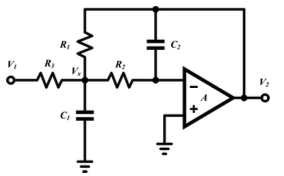

Transfer Function: $H\left(s\right)=\frac{\frac{G_2 G_3 }{C_1 C_2 }}{s^2 +s\left(\frac{G_1 {+G}_2 +G_3 }{C_1 }\right)+\frac{G_1 G_2 }{C_1 C_2 }+\varepsilon }$


$$\varepsilon =\frac{1}{A}\left\lbrack s^2 +s\left(\frac{G_1 +G_2 +G_3 }{C_1 }+\frac{G_2 }{C_2 }\right)+\frac{\left(G_1 +G_3 \right)G_2 }{C_1 C_2 }\right\rbrack$$


For an ideal op-amp, $A\to \infty$ leads to $\varepsilon \to 0$.  Thus, the DC Gain: $\lim_{s\to 0} H\left(s\right)=\;H\left(0\right)\;=\;\frac{\frac{G_2 G_3 }{C_1 C_2 }}{\frac{G_1 G_2 }{C_1 C_2 }}\;=\;\frac{G_3 }{G_1 }$

The transfer function for a general second order low-pass filter is given

$H\left(s\right)=\frac{A_v \;{\omega_0 }^2 }{s^2 +\frac{\omega_0 }{Q}s+{\omega_0 }^2 }$ ,  we got that $\omega_0^2 \;=\;\frac{G_1 G_2 }{C_1 C_2 }$   Thus, the pole frequency $\omega_0 \;=\;\sqrt{\frac{G_1 G_2 }{C_1 C_2 }}$

Pole Q is determined by the coefficient of *s* in the denominator

So we got  $\frac{\omega_0 }{Q_p }\;=\;\frac{G_1 {+G}_2 +G_3 }{C_1 }\;\to Q_p \;=\;\sqrt{\frac{G_1 G_2 }{C_1 C_2 }}\left(\frac{C_1 }{G_1 +G_2 +G_3 }\right)$

### 2. Design a Rauch filter for the following specifications:

###  $R_1 =1\;\textrm{kΩ}$, $R_2 =0\ldotp 5\;\textrm{kΩ}$, $DC\;gain=1$, $Q_p =2^{-\frac{1}{2}}$, $\omega_0 =40\pi \;krad/s$

#### Please output the performance characteristics of the filter (gain/frequency response/zero pole, etc.)

R1 = 1e3;            % 1k ohms
R2 = 500;            % 500 ohms
DC_gain = 1;         % DC Gain
Q_p = 2^(-0.5);      % Quality factor
w_0 = 40 * pi * 1e3; % Pole Frequency (rad/s)

G1 = 1/R1;
G2 = 1/R2;
G3 = G1*DC_gain; % H(0) = G3/G1

% Calculate C1 and C2
C1C2 = G1 * G2 / w_0^2;
C1 = Q_p * (G1 + G2 + G3) / w_0;
C2 = C1C2 / C1;
numerator = [0 , 0 , (G2 * G3)/(C1 * C2)];           % Numerator
denominator = [1 , (G1+G2+G3)/C1 , (G1*G2)/(C1*C2)]; % Denominator

tf_sys = tf(numerator, denominator);
fprintf('G1 = %.2f mho\nG2 = %.2f mho\nG3 = %.2f mho\nC1 = %.6e F\nC2 = %.6e F\nDC Gain = %.2f\nQ_p = %.4f\nw_0 = %.2f rad/s', G1, G2, G3, C1, C2, DC_gain, Q_p, w_0);

G1 = 0.00 ℧
G2 = 0.00 Ohms
G3 = 0.00 Ohms
C1 = 2.250791e-08 F
C2 = 5.626977e-09 F
DC Gain = 1.00
Q_p = 0.7071
w_0 = 125663.71 rad/s

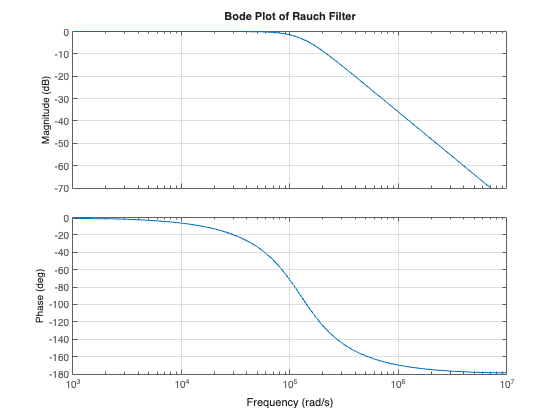

% Plot for gain and phase response
figure;
bode(tf_sys);
grid on;
title('Bode Plot of Rauch Filter');

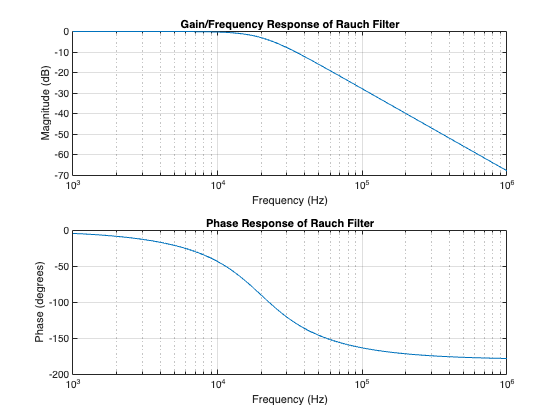

[H, w] = freqs(num, den);
% Magnitude response
figure('Position',[900 750 400 250]);
figure(2);
semilogx(w, 20*log10(abs(H)));
grid on
title("Magnitude response");
ylabel("Megnitude [dB]");
xlabel("Frequency [Hz]");
xline(2*pi*20e3);


% Frequency response
figure;
freqs = logspace(3, 6, 500); % Frequency range from 1 kHz to 1 MHz
[mag, phase, w] = bode(tf_sys, 2*pi*freqs);

% Magnitude plot
subplot(2, 1, 1);
semilogx(freqs, 20*log10(squeeze(mag)));
grid on;
title('Gain/Frequency Response of Rauch Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

% Phase plot
subplot(2, 1, 2);
semilogx(freqs, squeeze(phase));
grid on;
title('Phase Response of Rauch Filter');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');

% Poles and Zeros
[z, p, k] = tf2zp(numerator, denominator)

z =
  0×1 empty double column vector


p = 1.0e+04 *

  -8.8858 + 8.8858i
  -8.8858 - 8.8858i


k = 1.5791e+10

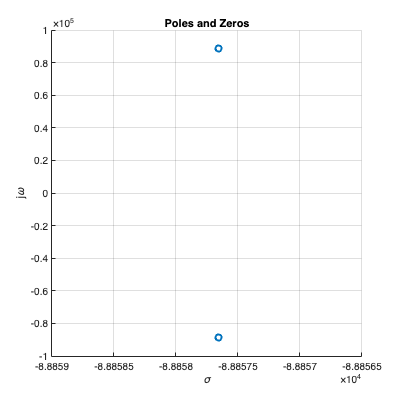


figure('Position',[400 600 400 400]);
plot(z,'o');
hold on
plot(p,'o', 'LineWidth',2);
title("Poles and Zeros");
ylabel("j\omega");
xlabel("\sigma");
grid on